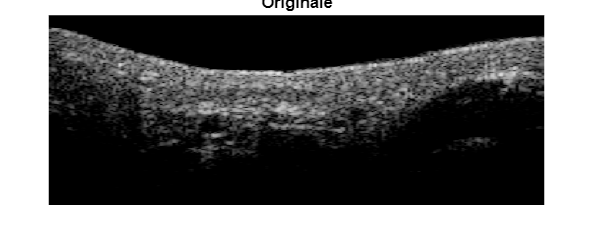

img = imread("Dati elaborati\b-scan estratti\26-07-2023_Luongo_000\26-07-2023_Luongo_000_200.bmp");
imshow(img);title("Originale");

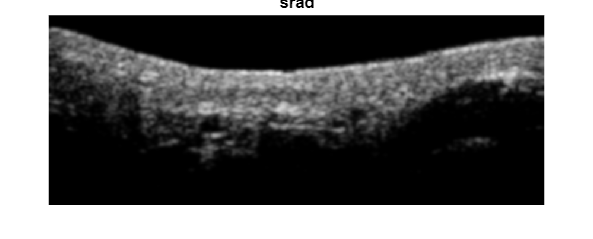

rect = [0 0 50 50];
srad = SRAD(img, 50, 0.2, rect);
imshow(srad);title("srad")

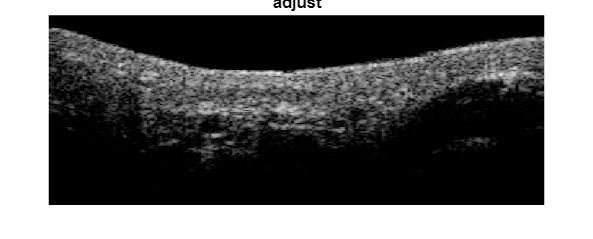

% Adjust data to span data range.
% srad = srad(round(5/0.0462):round(10/0.0462), round(10/0.0462):round(20/0.0462));
X = imadjust(srad);

imshow(img);title("adjust");

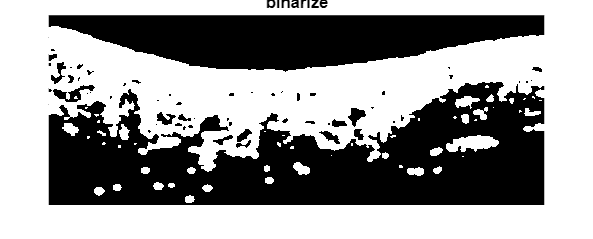

% Threshold image with adaptive threshold
BW = imbinarize(im2gray(X), 'adaptive', 'Sensitivity', 1.000000, 'ForegroundPolarity', 'bright');
imshow(BW);title("binarize");

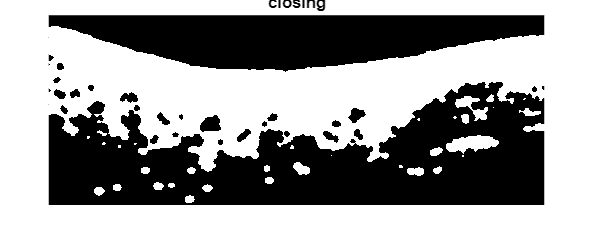

% Close mask with disk
radius = 4;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);
imshow(BW);title("closing");

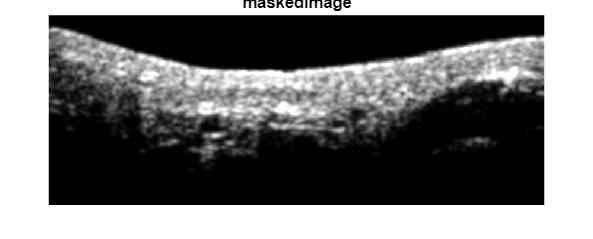

% Create masked image.
maskedImage = X;
imshow(maskedImage);title("maskedImage");

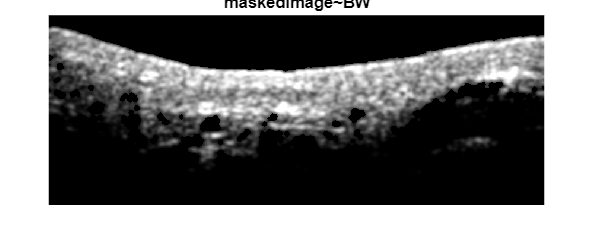

maskedImage(~BW) = 0;
imshow(maskedImage);title("maskedImage~BW");

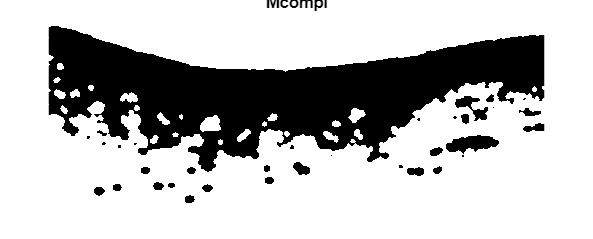

% Mlog = im2bw(BW); % converto in matrice logica
% imshow(Mlog);title("Mlog");
Mcompl = imcomplement(BW); %calcolo matrice complementare
imshow(Mcompl);title("Mcompl");

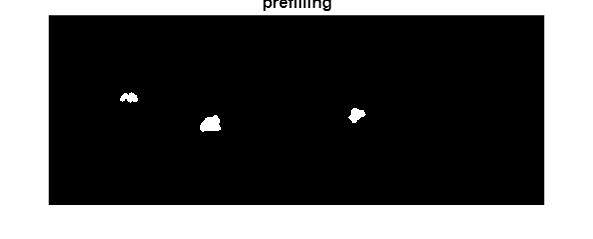

CC = bwconncomp(Mcompl);
S = regionprops(CC, 'Area');
L = labelmatrix(CC);
BW = ismember(L, find([S.Area] < 1300 & [S.Area] > 350));
imshow(BW);title("prefilling");

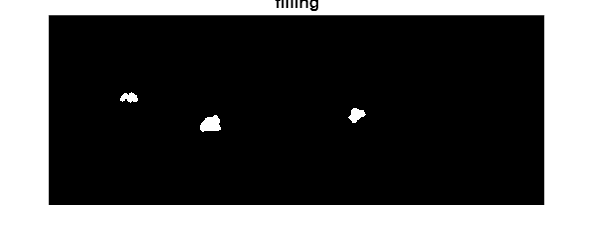

BW = imfill(BW,'holes');
imshow(BW);title("filling");

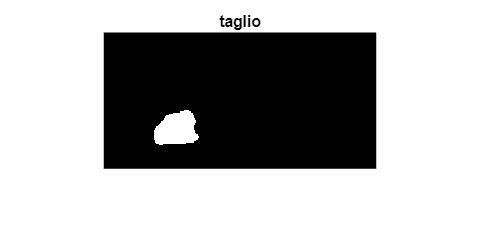

BW = BW(round(5/0.0462):round(10/0.0462), round(10/0.0462):round(20/0.0462));
imshow(BW);title("taglio");

% Estrai le caratteristiche dalle vene segmentate
vein_properties = regionprops(BW, 'Area', 'Perimeter', 'MajorAxisLength', 'MinorAxisLength', 'Eccentricity', 'Centroid', 'BoundingBox');

% Inizializza vettori per le caratteristiche
vein_lengths = [];
vein_widths = [];
vein_shapes = [];
vein_dispositions = [];

for i = 1:numel(vein_properties)
    % Estrai le proprietà per ciascuna vena
    area = vein_properties(i).Area;
    perimeter = vein_properties(i).Perimeter;
    major_axis_length = vein_properties(i).MajorAxisLength;
    minor_axis_length = vein_properties(i).MinorAxisLength;
    eccentricity = vein_properties(i).Eccentricity;
    centroid = vein_properties(i).Centroid;
    bounding_box = vein_properties(i).BoundingBox;

    % Calcola le caratteristiche desiderate
    length = major_axis_length;
    width = minor_axis_length;
    shape = 4 * pi * area / perimeter^2;  % Calcola un'indicazione della forma (circolarità)
    disposition = centroid;  % Utilizza la posizione del centroide come disposizione

    % Aggiungi le caratteristiche ai vettori
    vein_lengths = [vein_lengths; length];
    vein_widths = [vein_widths; width];
    vein_shapes = [vein_shapes; shape];
    vein_dispositions = [vein_dispositions; disposition];
end

% % Creazione di un'immagine vuota delle stesse dimensioni dell'immagine originale
% outputImage = zeros(round(300),round(835));
% 
% 
% for i = 1:numel(vein_properties)
%     centroid = vein_properties(i).Centroid;
%     x = round(centroid(1)); % Coordinata x del centroide
%     y = round(150 ); % Coordinata y fissa come specificato
% 
%     % Disegna il pixel nelle coordinate specificate
%     outputImage(x, y) = 255; % Imposta il valore del pixel a bianco (255)
% end
% 
% 
% % outputImage = imresize(outputImage, 10);
% imshow(outputImage)


% % Dimensioni dell'immagine template
% img_size = 800; % Modifica la dimensione dell'immagine secondo necessità
% 
% % Creazione dell'immagine template
% template_image = zeros(320, 835);
% 
% for i = 1:numel(vein_shapes)
%     % Calcola le dimensioni proporzionali
%     length =  vein_lengths(i);
%     width =  vein_widths(i);
% 
%     % Centro dell'ellisse nell'immagine template
%     centroid_vein = vein_properties(i).Centroid;
%     center_x = centroid_vein(1);
%     center_y = centroid_vein(2);
% 
%     % Creazione di un'ellisse all'interno delle dimensioni dell'immagine
%     [X, Y] = meshgrid(1:835, 1:320);
%     ellipse = ((X - center_x).^2 / (width/2)^2 + (Y - center_y).^2 / (length/2)^2) <= 1;
% 
%     % Assegna la forma specifica della vena all'ellisse dell'immagine template
%     % Assegna la forma specifica della vena all'ellisse dell'immagine template
%     template_image = template_image + ellipse * vein_shapes(i);
% end
% imshow(template_image);

% % Calcola la lunghezza totale dei vasi (somma dei pixel bianchi)
% totalLength = sum(BW(:));
%
% % Calcola l'area totale dei vasi (numero di pixel bianchi)
% totalArea = nnz(BW);
%
% % Trova i vasi connessi e conta il loro numero
% CC = bwconncomp(BW);
% numConnectedVessels = CC.NumObjects;
%
% % Calcola la media e la deviazione standard dell'intensità dei pixel nei vasi
% vesselIntensities = double(BW) .* double(img);
% vesselIntensities = vesselIntensities(vesselIntensities > 0);
% meanIntensity = mean(vesselIntensities);
% stdIntensity = std(vesselIntensities);
%
% % Organizza le caratteristiche in un vettore
% features = [totalLength, totalArea, numConnectedVessels, meanIntensity, stdIntensity];